clear all
clc

% parameter
% link length
l1 = 0.33; % l1 = 0.33
l2 = 0.33;
l3 = 0.33;
l4 = 0.33; % l1 = 0.33

% link masses
% link masses
m1 = 0.1; %0.1
m2 = 0.1;
m3 = 0.1;
m4 = 0.1;

% link inertias
I1 = [ 1 1 1 0 0 0]; %[Ixx Iyy Izz Iyz Ixz Ixy]. %[ 1 1 1 0 0 0]
I2 = [ 1 1 1 0 0 0];
I3 = [ 1 1 1 0 0 0];
I4 = [ 1 1 1 0 0 0];


% COM
COM1 = [l1/2 0 0]; % [x y z] in body frame
COM2 = [l2/2 0 0]; % [x y z] in body frame
COM3 = [l3/2 0 0]; % [x y z] in body frame
COM4 = [l4/2 0 0]; % [x y z] in body frame

% dh params
% [a alpha d theta]
dhparams = [ 0 0 0 0;
            l1 0 0 0;
            l2 pi/2 0 pi;
            l3 0 0 0;
            l4 0 0 0];
            

% create robot
robot = rigidBodyTree

robot =   rigidBodyTree with properties:

     NumBodies: 0
        Bodies: {1×0 cell}
          Base: [1×1 rigidBody]
     BodyNames: {1×0 cell}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'struct'



% define bodies and Joints
jnt1 = rigidBodyJoint('jnt1','revolute');
body1 = rigidBody('link_1');
body1.Mass = m1;
body1.CenterOfMass = COM1;
body1.Inertia = I1;

jnt2 = rigidBodyJoint('jnt2','revolute');
body2 = rigidBody('link_2');
body2.Mass = m2;
body2.CenterOfMass = COM2;
body2.Inertia = I2;

jnt3 = rigidBodyJoint('jnt3','revolute');
body3 = rigidBody('link_3');
body3.Mass = m3;
body3.CenterOfMass = COM3;
body2.Inertia = I3;

jnt4 = rigidBodyJoint('jnt4','revolute');
body4 = rigidBody('link_4');
body4.Mass = m4;
body4.CenterOfMass = COM4;
body4.Inertia = I4;


endeff = rigidBody('link_ee');
endeff.Mass = 0;
endeff.CenterOfMass = 0*COM3;
endeff.Inertia = 0*I3;



% set frame transforms
setFixedTransform(jnt1,dhparams(1,:),'mdh');
setFixedTransform(jnt2,dhparams(2,:),'mdh');
setFixedTransform(jnt3,dhparams(3,:),'mdh');
setFixedTransform(jnt4,dhparams(4,:),'mdh');
setFixedTransform(endeff.Joint,dhparams(5,:),'mdh');

% Assign these Joints to the body
body1.Joint = jnt1;
body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;

% Add these rigid bodies to the tree
addBody(robot,body1,'base')
addBody(robot,body2,'link_1')
addBody(robot,body3,'link_2')
addBody(robot,body4,'link_3')
addBody(robot,endeff,'link_4')

robot.DataFormat = 'column';

showdetails(robot)

--------------------
Robot: (5 bodies)

 Idx      Body Name         Joint Name         Joint Type      Parent Name(Idx)   Children Name(s)
 ---      ---------         ----------         ----------      ----------------   ----------------
   1         link_1               jnt1           revolute               base(0)   link_2(2)  
   2         link_2               jnt2           revolute             link_1(1)   link_3(3)  
   3         link_3               jnt3           revolute             link_2(2)   link_4(4)  
   4         link_4               jnt4           revolute             link_3(3)   link_ee(5)  
   5        link_ee        link_ee_jnt              fixed             link_4(4)   
--------------------


dt = 0.005;
num_snaps = 1000;
num_traj = 200;
t_span = 0:dt:dt*num_snaps;
num_states = length(homeConfiguration(robot));

% % % Initialize the values
% X(1:num_states,1) = (pi/2)*(2*rand(num_states,1) - 1); %joint angles
% X(num_states+1:2*num_states,1) = 0.1*(2*rand(num_states,1) - 1); %joint velocity
% tf = getTransform(robot,X(1:num_states,1),'link_ee');
% X_end(:,1) = tf(1:3,4);
% for i = 1:num_snaps
%     tau(:,i) = 0.1*(2*rand(1,num_states) - 1); %input torques
% 
%     th_ddot = forwardDynamics(robot,X(1:num_states,i),X(num_states+1:2*num_states,i),tau(:,i));
% 
%     X(num_states+1:2*num_states,i+1) = th_ddot*dt + X(num_states+1:2*num_states,i);
%     X(1:num_states,i+1) = th_ddot*dt + X(1:num_states,i);
% 
%     tf = getTransform(robot,X(1:num_states,i+1),'link_ee');
%     X_end(:,i+1) = tf(1:3,4);
% 
% end
% 
% for i = 1:(num_snaps)/10
%     wp(:,i) = robot.randomConfiguration;
% end
% 
% t_wp = linspace(0,dt*num_snaps,size(wp,2));
% 
% [X(1:num_states,:),X(num_states+1:2*num_states,:), th_ddot] =  minjerkpolytraj(wp, t_wp, num_snaps);
% 
% 
% for i = 1:num_snaps
%     tau(:,i) = inverseDynamics(robot,X(1:num_states,i),X(num_states+1:2*num_states,i),th_ddot(:,i));
% 
%     tf = getTransform(robot,X(1:num_states,i),'link_ee');
%     X_end(:,i) = tf(1:3,4);
% 
% end

% % 3D
% for i = 1:num_traj
%     Initialize the values
%     X(i,1,1:num_states) = (pi/2)*(2*rand(num_states,1) - 1); %joint angles
%     X(i,1,num_states+1:2*num_states) = 0.1*(2*rand(num_states,1) - 1); %joint velocity
%     tf = getTransform(robot,reshape(X(i,1,1:num_states),[num_states,1]),'link_ee');
%     X_end(i,1,:) = tf(1:3,4);
%     for j = 1:num_snaps
%         th_ddot = (2*pi/3)*(2*rand(num_states,1) - 1);
%         tau(i,j,:) = inverseDynamics(robot,reshape(X(i,j,1:num_states),[num_states,1]),reshape(X(i,j,num_states+1:2*num_states),[num_states,1]),th_ddot);
% 
%         X(i,j+1,num_states+1:2*num_states) = reshape(th_ddot,[1,1,num_states])*dt + X(i,j,num_states+1:2*num_states);
%         X(i,j+1,1:num_states) = X(i,j,num_states+1:2*num_states)*dt + X(i,j,1:num_states);
% 
%         tf = getTransform(robot,reshape(X(i,j+1,1:num_states),[num_states,1]),'link_ee');
%         X_end(i,j+1,:) = tf(1:3,4);
% 
%     end
% end

% % 2D
% for i = 1:num_traj
%     ul_joints = [0;1;0;1;0;1;0];
%     l_joints= [-0.0;-1;0.0;-1.65;-0.0;-1.3;0.0];
%     Initialize the values
%     X(i,1,1:num_states) = (pi/2)*(2*rand(num_states,1) - 1).*ul_joints + l_joints; %joint angles
%     X(i,1,num_states+1:2*num_states) = 0.1*(2*rand(num_states,1) - 1).*ul_joints; %joint velocity
%     tf = getTransform(robot,reshape(X(i,1,1:num_states),[num_states,1]),'link_ee');
%     X_end(i,1,:) = tf(1:3,4);
%     for j = 1:num_snaps
%         th_ddot = (pi/4)*(2*rand(num_states,1) - 1).*ul_joints;
%         tau(i,j,:) = inverseDynamics(robot,reshape(X(i,j,1:num_states),[num_states,1]),reshape(X(i,j,num_states+1:2*num_states),[num_states,1]),th_ddot);
% 
%         X(i,j+1,num_states+1:2*num_states) = reshape(th_ddot,[1,1,num_states])*dt + X(i,j,num_states+1:2*num_states);
%         X(i,j+1,1:num_states) = X(i,j,num_states+1:2*num_states)*dt + X(i,j,1:num_states);
% 
%         tf = getTransform(robot,reshape(X(i,j+1,1:num_states),[num_states,1]),'link_ee');
%         X_end(i,j+1,:) = tf(1:3,4);
% 
%     end
% end

% for i = 1:num_traj
%     ul_joints = [0;1;0;1;0;1;0];
%     l_joints= [-0.0;-1;0.0;-1.65;-0.0;-1.3;0.0];
%     Initialize the values
%     X(i,1,1:num_states) = (pi/2)*(2*rand(num_states,1) - 1).*ul_joints + l_joints; %joint angles
%     X(i,1,num_states+1:2*num_states) = 0.1*(2*rand(num_states,1) - 1).*ul_joints; %joint velocity
%     tf = getTransform(robot,reshape(X(i,1,1:num_states),[num_states,1]),'link_ee');
%     X_end(i,1,:) = tf(1:3,4);
%     for j = 1:num_snaps
%         tau(i,j,:) = (2*rand(num_states,1) - 1).*ul_joints;
%         th_ddot = forwardDynamics(robot,reshape(X(i,j,1:num_states),[num_states,1]),reshape(X(i,j,num_states+1:2*num_states),[num_states,1]),reshape(tau(i,j,:),[num_states,1]));
% 
%         X(i,j+1,num_states+1:2*num_states) = reshape(th_ddot,[1,1,num_states])*dt + X(i,j,num_states+1:2*num_states);
%         X(i,j+1,1:num_states) = X(i,j,num_states+1:2*num_states)*dt + X(i,j,1:num_states);
% 
%    q_wp(:,1) = randomConfiguration(kuka)'     
%    tf = getTransform(kuka,reshape(X(i,j+1,1:num_states),[num_states,1]),'link_ee');
%    X_end(i,j+1,:) = tf(1:3,4);
% 
%     end
% end

% % % input are sines
% for i = 1:num_traj
%     ul_joints = [0;1;0;1;0;1;0];
%     tau_joints = [1;1;1;1;1;0.1;0.1];
%     l_joints= [-0.0;-1;0.0;-1.65;-0.0;-1.3;0.0];
%     Initialize the values
%     X(i,1,1:num_states) = (pi/2)*(2*rand(num_states,1) - 1).*ul_joints + l_joints; %joint angles
%     X(i,1,num_states+1:2*num_states) = 0.1*(2*rand(num_states,1) - 1).*ul_joints; %joint velocity
%     tf = getTransform(robot,reshape(X(i,1,1:num_states),[num_states,1]),'link_ee');
%     X_end(i,1,:) = tf(1:3,4);
%     phase = pi*(2*rand(num_states,1) - 1);
%     amp = (2*rand(num_states,1) - 1);
%     freq = 5*rand(num_states,1);
%     for j = 1:num_snaps
%         tau(i,j,:) = amp.*sin(freq*pi*(j/num_snaps) + phase).*tau_joints;
%         th_ddot = forwardDynamics(robot,reshape(X(i,j,1:num_states),[num_states,1]),reshape(X(i,j,num_states+1:2*num_states),[num_states,1]),reshape(tau(i,j,:),[num_states,1]));
% 
%         X(i,j+1,num_states+1:2*num_states) = reshape(th_ddot,[1,1,num_states])*dt + X(i,j,num_states+1:2*num_states);
%         X(i,j+1,1:num_states) = X(i,j,num_states+1:2*num_states)*dt + X(i,j,1:num_states);
% 
%         tf = getTransform(robot,reshape(X(i,j+1,1:num_states),[num_states,1]),'link_ee');
%         X_end(i,j+1,:) = tf(1:3,4);
% 
%     end
% end

% % % input are sines
% for i = 1:num_traj
%     ul_joints = [0;1;0;1;0;1;0];
%     tau_joints = [0;1;0;1;0;0.1;0];
%     l_joints= 0*[-0.0;-1;0.0;-1.65;-0.0;-1.3;0.0];
%     Initialize the values
%     X(i,1,1:num_states) = (pi/2)*(2*rand(num_states,1) - 1).*ul_joints + l_joints; %joint angles
%     X(i,1,num_states+1:2*num_states) = 0.1*(2*rand(num_states,1) - 1).*ul_joints; %joint velocity
%     tf = getTransform(robot,reshape(X(i,1,1:num_states),[num_states,1]),'link_ee');
%     X_end(i,1,:) = tf(1:3,4);
%     phase = pi*(2*rand(num_states,1) - 1);
%     amp = (2*rand(num_states,1) - 1);
%     freq = 5*rand(num_states,1);
%     for j = 1:num_snaps
%         tau(i,j,:) = amp.*sin(freq*pi*(j/num_snaps) + phase).*tau_joints;
%         th_ddot = forwardDynamics(robot,reshape(X(i,j,1:num_states),[num_states,1]),reshape(X(i,j,num_states+1:2*num_states),[num_states,1]),reshape(tau(i,j,:),[num_states,1]));
% 
%         X(i,j+1,num_states+1:2*num_states) = reshape(th_ddot,[1,1,num_states])*dt + X(i,j,num_states+1:2*num_states);
%         X(i,j+1,1:num_states) = X(i,j,num_states+1:2*num_states)*dt + X(i,j,1:num_states);
% 
%         tf = getTransform(robot,reshape(X(i,j+1,1:num_states),[num_states,1]),'link_ee');
%         X_end(i,j+1,:) = tf(1:3,4);
% 
%     end
% end

% % % input are sines
% for i = 1:num_traj
%     ul_joints = [0;1;0;1;0;1;0];
%     tau_joints = [1;10;1;1;0.1;0.1;0.1];
%     l_joints= 0*[-0.0;-1;0.0;-1.65;-0.0;-1.3;0.0];
%     % Initialize the values
%     X(i,1,1:num_states) = (pi/2)*(2*rand(num_states,1) - 1);%.*ul_joints + l_joints; %joint angles
%     X(i,1,num_states+1:2*num_states) = 0.1*(2*rand(num_states,1) - 1);%.*ul_joints; %joint velocity
%     tf = getTransform(robot,reshape(X(i,1,1:num_states),[num_states,1]),'link_ee');
%     X_end(i,1,:) = tf(1:3,4);
%     phase = pi*(2*rand(num_states,1) - 1);
%     amp = (2*rand(num_states,1) - 1);
%     freq = 4*rand(num_states,1);
%     for j = 1:num_snaps
%         th_ddot = amp.*sin(freq*pi*(j/num_snaps) + phase);%.*tau_joints;
%         %th_ddot = amp.*(2*rand(num_states,1) - 1).*tau_joints;
%         tau(i,j,:) = inverseDynamics(robot,reshape(X(i,j,1:num_states),[num_states,1]),reshape(X(i,j,num_states+1:2*num_states),[num_states,1]),th_ddot);
% 
%         X(i,j+1,num_states+1:2*num_states) = reshape(th_ddot,[1,1,num_states])*dt + X(i,j,num_states+1:2*num_states);
%         X(i,j+1,1:num_states) = X(i,j,num_states+1:2*num_states)*dt + X(i,j,1:num_states);
% 
%         tf = getTransform(robot,reshape(X(i,j+1,1:num_states),[num_states,1]),'link_ee');
%         X_end(i,j+1,:) = tf(1:3,4);
% 
%     end
% end

% % controller
% 
% Kp = 16*eye(num_states);
% Kv = 8*eye(num_states);
% num_wp = 20;
% flag = 'random'; %'controlled'
% 
% for i = 1:num_traj
%     i
%     ul_joints = [0;1;0;1;0;1;0];
%     tau_joints = [1;10;1;1;0.1;0.1;0.1];
%     l_joints= 0*[-0.0;-1;0.0;-1.65;-0.0;-1.3;0.0];
% 
% 
%     % generate path
%     t_end = dt*num_snaps; 
%     for s = 1:num_wp
%         if s == 1
%             q_wp(:,1) = randomConfiguration(robot)';
%             t_wp(:,1) = 0;
%             q_wp_dot = 0.5*(2*rand(num_states,1) - 1);
%         else
%             t_wp(s) = s*t_end/num_wp;
% %             q_wp(:,s) = randomConfiguration(kuka)';
%             q_wp(:,s) = q_wp(:,s-1) + q_wp_dot*(t_wp(s)-t_wp(s-1));
%             q_wp_dot = (2*rand(num_states,1) - 1);
%         end
% 
%     end
% 
%     [q_traj, qd_traj, qddot_traj] = minjerkpolytraj(q_wp,t_wp,length(t_span));
% 
% 
%     % Initialize the values
%     X(i,1,1:num_states) = q_traj(:,1);%.*ul_joints + l_joints; %joint angles
%     X(i,1,num_states+1:2*num_states) = qd_traj(:,1);%.*ul_joints; %joint velocity
%     tf = getTransform(robot,reshape(X(i,1,1:num_states),[num_states,1]),'link_ee');
%     X_end(i,1,:) = tf(1:3,4);
%     for j = 1:num_snaps
% 
%         tau_dash(:,j) = qddot_traj(:,j) + Kv*(qd_traj(:,j) - reshape(X(i,j,num_states+1:2*num_states),[num_states,1])) + Kp*(q_traj(:,j) - reshape(X(i,j,1:num_states),[num_states,1]));
%         tau(i,j,:) = massMatrix(robot, reshape(X(i,j,1:num_states),[num_states,1]))*tau_dash(:,j) + velocityProduct(robot, reshape(X(i,j,1:num_states),[num_states,1]), reshape(X(i,j,num_states+1:2*num_states),[num_states,1])) ... 
%                    + gravityTorque(robot, reshape(X(i,j,1:num_states),[num_states,1]));
% 
%         th_ddot = forwardDynamics(robot, reshape(X(i,j,1:num_states),[num_states,1]), reshape(X(i,j,num_states+1:2*num_states),[num_states,1]), reshape(tau(i,j,:),[num_states,1]));
%         %th_ddot = amp.*(2*rand(num_states,1) - 1).*tau_joints;
% 
% 
%         X(i,j+1,num_states+1:2*num_states) = reshape(th_ddot,[1,1,num_states])*dt + X(i,j,num_states+1:2*num_states);
%         X(i,j+1,1:num_states) = X(i,j,num_states+1:2*num_states)*dt + X(i,j,1:num_states);
% 
%         tf = getTransform(robot,reshape(X(i,j+1,1:num_states),[num_states,1]),'link_ee');
%         X_end(i,j+1,:) = tf(1:3,4);
% 
%     end
% end

% controller

Kp = 16*eye(num_states);
Kv = 8*eye(num_states);
num_wp = 20;
flag = 'random'; %'controlled'

for i = 1:num_traj
    i
    ul_joints = [0;1;0;1;0;1;0];
    tau_joints = [1;10;1;1;0.1;0.1;0.1];
    l_joints= 0*[-0.0;-1;0.0;-1.65;-0.0;-1.3;0.0];

    
    % generate path
    t_end = dt*num_snaps; 
    for s = 1:num_wp
        if s == 1
            q_wp(:,1) = randomConfiguration(robot)';
            t_wp(:,1) = 0;
            q_wp_dot = 0.1*(2*rand(num_states,1) - 1);
        else
            t_wp(s) = s*t_end/num_wp;
%             q_wp(:,s) = randomConfiguration(kuka)';
            q_wp(:,s) = q_wp(:,s-1) + q_wp_dot*(t_wp(s)-t_wp(s-1));
            q_wp_dot = 0.1*(2*rand(num_states,1) - 1);
        end

    end
    
    [q_traj, qd_traj, qddot_traj] = minjerkpolytraj(q_wp,t_wp,length(t_span));


    % Initialize the values
    X(i,1,1:num_states) = q_traj(:,1);%.*ul_joints + l_joints; %joint angles
    X(i,1,num_states+1:2*num_states) = qd_traj(:,1);%.*ul_joints; %joint velocity
    % X(i,1,2*num_states+1:3*num_states) = qddot_traj(:,1);
    tf = getTransform(robot,reshape(X(i,1,1:num_states),[num_states,1]),'link_ee');
    X_end(i,1,:) = tf(1:3,4);
    for j = 1:num_snaps

        tau_dash(:,j) = qddot_traj(:,j) + Kv*(qd_traj(:,j) - reshape(X(i,j,num_states+1:2*num_states),[num_states,1])) + Kp*(q_traj(:,j) - reshape(X(i,j,1:num_states),[num_states,1]));
        tau(i,j,:) = massMatrix(robot, reshape(X(i,j,1:num_states),[num_states,1]))*tau_dash(:,j) + velocityProduct(robot, reshape(X(i,j,1:num_states),[num_states,1]), reshape(X(i,j,num_states+1:2*num_states),[num_states,1])) ... 
                   + gravityTorque(robot, reshape(X(i,j,1:num_states),[num_states,1]));

        th_ddot = forwardDynamics(robot, reshape(X(i,j,1:num_states),[num_states,1]), reshape(X(i,j,num_states+1:2*num_states),[num_states,1]), reshape(tau(i,j,:),[num_states,1]));
        %th_ddot = amp.*(2*rand(num_states,1) - 1).*tau_joints;
  
    
        % X(i,j+1,2*num_states+1:3*num_states) = th_ddot;
        X(i,j+1,num_states+1:2*num_states) = reshape(th_ddot,[1,1,num_states])*dt + X(i,j,num_states+1:2*num_states);
        X(i,j+1,1:num_states) = X(i,j,num_states+1:2*num_states)*dt + X(i,j,1:num_states);
    
        tf = getTransform(robot,reshape(X(i,j+1,1:num_states),[num_states,1]),'link_ee');
        X_end(i,j+1,:) = tf(1:3,4);
    
    end
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

i = 121

i = 122

i = 123

i = 124

i = 125

i = 126

i = 127

i = 128

i = 129

i = 130

i = 131

i = 132

i = 133

i = 134

i = 135

i = 136

i = 137

i = 138

i = 139

i = 140

i = 141

i = 142

i = 143

i = 144

i = 145

i = 146

i = 147

i = 148

i = 149

i = 150

i = 151

i = 152

i = 153

i = 154

i = 155

i = 156

i = 157

i = 158

i = 159

i = 160

i = 161

i = 162

i = 163

i = 164

i = 165

i = 166

i = 167

i = 168

i = 169

i = 170

i = 171

i = 172

i = 173

i = 174

i = 175

i = 176

i = 177

i = 178

i = 179

i = 180

i = 181

i = 182

i = 183

i = 184

i = 185

i = 186

i = 187

i = 188

i = 189

i = 190

i = 191

i = 192

i = 193

i = 194

i = 195

i = 196

i = 197

i = 198

i = 199

i = 200

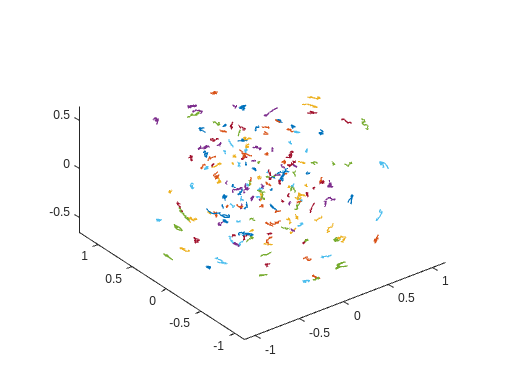

figure()
for i = 1:num_traj
    plot3(X_end(i,:,1),X_end(i,:,2),X_end(i,:,3), 'LineWidth',1)
    hold on
end
axis('equal')

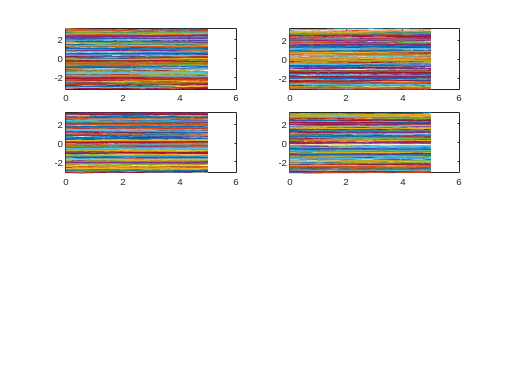

figure()
for i = 1:num_states
    subplot(4,2,i)
    xlabel('t')
    ylabel(strcat('th',num2str(i)))
    for j = 1:num_traj
        plot(t_span,X(j,:,i))
        hold on

    end
end

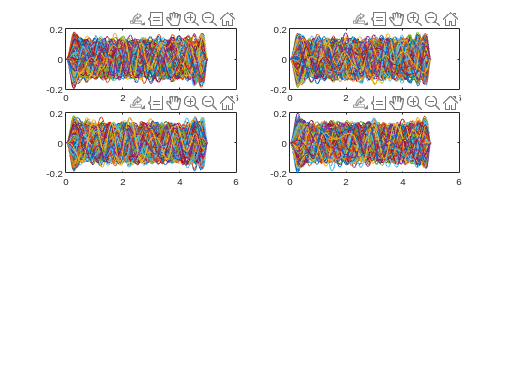

figure()
for i = 1:num_states
    subplot(4,2,i)
    xlabel('t')
    ylabel(strcat('th dot ',num2str(i)))
    for j = 1:num_traj
        plot(t_span,X(j,:,i+num_states))
        hold on

    end
end

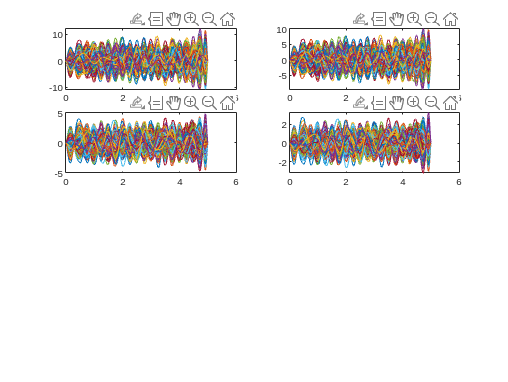

figure()
for i = 1:num_states
    subplot(4,2,i)
    xlabel('t')
    ylabel(strcat('tau',num2str(i)))
    for j = 1:num_traj
        plot(t_span(1:end-1),tau(j,:,i))
        hold on

    end
end


[q_traj, qd_traj, qddot_traj] = minjerkpolytraj(q_wp,t_wp,length(t_span));

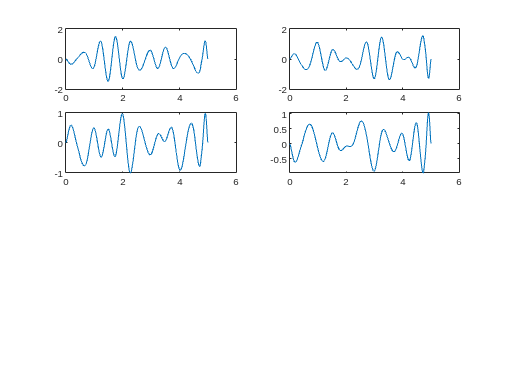

figure()
for i = 1:num_states
    subplot(4,2,i)
    plot(t_span(1:end-1),tau_dash(i,:))
end

% X = X(:,:,[2,4,6,9,11,13]);
% tau = tau(:,:,[2,4,6]);

% save("dynamics\Dataset_MATLAB\X.mat","X")
% save("dynamics\Dataset_MATLAB\X_end.mat","Xend")
% save("dynamics\Dataset_MATLAB\U.mat","tau")


save("dynamics/Dataset_MATLAB/4R/3D/data.mat","X_end","X","tau",'dt','num_snaps',"num_traj")
% save("dynamics\Dataset_MATLAB\X_end.mat","X_end")
% save("dynamics\Dataset_MATLAB\U.mat","tau")



for i = 1:num_traj
    i

    for j = 1:num_snaps

        X_fw(i,j, 1:num_states) = randomConfiguration(robot);
        hom_tf = getTransform(robot,reshape(X_fw(i,j,1:num_states),[num_states,1]),'link_ee');
        X_end_fw(i,j,:) = hom_tf(1:3,4);

    end
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

i = 121

i = 122

i = 123

i = 124

i = 125

i = 126

i = 127

i = 128

i = 129

i = 130

i = 131

i = 132

i = 133

i = 134

i = 135

i = 136

i = 137

i = 138

i = 139

i = 140

i = 141

i = 142

i = 143

i = 144

i = 145

i = 146

i = 147

i = 148

i = 149

i = 150

i = 151

i = 152

i = 153

i = 154

i = 155

i = 156

i = 157

i = 158

i = 159

i = 160

i = 161

i = 162

i = 163

i = 164

i = 165

i = 166

i = 167

i = 168

i = 169

i = 170

i = 171

i = 172

i = 173

i = 174

i = 175

i = 176

i = 177

i = 178

i = 179

i = 180

i = 181

i = 182

i = 183

i = 184

i = 185

i = 186

i = 187

i = 188

i = 189

i = 190

i = 191

i = 192

i = 193

i = 194

i = 195

i = 196

i = 197

i = 198

i = 199

i = 200


save("dynamics/Dataset_MATLAB/4R/3D/data_fw.mat","X_end_fw","X_fw",'dt','num_snaps',"num_traj")
